# RefMap tonality/tonal loudness proxy metric development

## Setup

Last modified: 09/02/2026

% choose SHM ECMA-418-2 directory for processing
shmPath = uigetdir("", "Select ECMA-418-2 refmap-psychoacoustics\src\mlab\ root directory");
addpath(genpath(shmPath))

% choose output directory for data files
outputPath = uigetdir("", "Select output directory \02 Delivery\Psychoacoustic metrics");
addpath(outputPath)

% choose input directory for hover audio files
hoverPath = uigetdir(outputPath, "Select input directory \02 Delivery\Psychoacoustic metrics\Auralisations\SynthesisedHovering");
addpath(hoverPath)

% choose input directory for overflight audio files
flightPath = uigetdir(outputPath, "Select input directory \02 Delivery\Psychoacoustic metrics\Auralisations\SynthesisedOverflight");
addpath(flightPath)

% custom colour palette for line plotting
mycolours = [0, 102, 255;
             0, 204, 153;
             255, 0, 102;
             74, 111, 152;
             231, 144, 29; %251, 164, 49;
             204, 153, 255;
             90, 192, 255;
             90, 255, 243;
             255, 110, 212;
             164, 201, 242;
             255, 254, 139;
             255, 243, 255]./255;

## Recalibrate relative gains for overflight files

The propagated render files are normalised, so the components need to be recalibrated to the relative gains that are obtained from the unpropagated synthesised files. Then the recalibrated renders are saved into the root directory for further analysis

% list overflight folders
dirContents = dir(flightPath);
nameContents = string({dirContents.name}.');
fileFolders = string({dirContents(nameContents ~= '.' & nameContents ~= '..').folder}.') + filesep + string({dirContents(nameContents ~= '.' & nameContents ~= '..').name}.');

for ii = 1:length(fileFolders)
    folder = fileFolders(ii);
    wavContents = string(ls(strcat(folder + filesep + '*.wav*')));
    wavContents = string(cellfun(@strip, wavContents, 'UniformOutput', false));
    
    % back-propagated overflights
    totalFile = wavContents(contains(wavContents, 'Total') & ~contains(wavContents, 'Propagated'));
    [pTotal, fsTotal] = audioread(fullfile(folder, totalFile));
    pTotalPeak = max(abs(pTotal));
    pTotalRMS = rms(pTotal);

    % back propagation distance (used to adjust overflight renders)
    if contains(totalFile, "_X")
        backProp = 5;  % for the XAG P40
    else
        backProp = 1;
    end

    bBandFile = wavContents(contains(wavContents, 'BroadBand') & ~contains(wavContents, 'Propagated'));
    [pBBand, fsBBand] = audioread(fullfile(folder, bBandFile));
    pBBandRMS = rms(pBBand);
    pBBandRMS_pTotalRMS = pBBandRMS/pTotalRMS;

    tonalFile = wavContents(contains(wavContents, 'Tonal') & ~contains(wavContents, 'Propagated'));
    [pTonal, fsTonal] = audioread(fullfile(folder, tonalFile));
    pTonalRMS = rms(pTonal);
    pTonalRMS_pTotalRMS = pTonalRMS/pTotalRMS;

    % 10 m overflight
    totalProp10File = wavContents(contains(wavContents, 'Total') & contains(wavContents, 'Propagated_10'));
    [pTotal10, fsTotal10] = audioread(fullfile(folder, totalProp10File));
    pTotal10Peak = max(abs(pTotal10));
    pTotal10 = pTotal10./pTotal10Peak.*pTotalPeak.*backProp./10;  % first, adjust the total peak pressure to the correct value at 10 m
    pTotal10RMS = rms(pTotal10);

    bBandProp10File = wavContents(contains(wavContents, 'BroadBand') & contains(wavContents, 'Propagated_10'));
    [pBBand10, fsBBand10] = audioread(fullfile(folder, bBandProp10File));
    pBBand10 = pBBand10.*backProp./10;  % adjust it to 10 m
    pBBand10RMS = rms(pBBand10);
    pBBand10 = pBBand10./pBBand10RMS.*pBBandRMS_pTotalRMS.*pTotal10RMS;  % adjust it so that the energy ratio to the total is the same as for the back-prop

    tonalProp10File = wavContents(contains(wavContents, 'Tonal') & contains(wavContents, 'Propagated_10'));
    [pTonal10, fsTonal10] = audioread(fullfile(folder, tonalProp10File));
    pTonal10 = pTonal10.*backProp./10;  % adjust it to 10 m
    pTonal10RMS = rms(pTonal10);
    pTonal10 = pTonal10./pTonal10RMS.*pTonalRMS_pTotalRMS.*pTotal10RMS;  % adjust it so that the energy ratio to the total is the same as for the back-prop

    % 25 m overflight
    totalProp25File = wavContents(contains(wavContents, 'Total') & contains(wavContents, 'Propagated_25'));
    [pTotal25, fsTotal25] = audioread(fullfile(folder, totalProp25File));
    pTotal25Peak = max(abs(pTotal25));
    pTotal25 = pTotal25./pTotal25Peak.*pTotalPeak.*backProp./25;  % first, adjust the total peak pressure to the correct value at 25 m
    pTotal25RMS = rms(pTotal25);

    bBandProp25File = wavContents(contains(wavContents, 'BroadBand') & contains(wavContents, 'Propagated_25'));
    [pBBand25, fsBBand25] = audioread(fullfile(folder, bBandProp25File));
    pBBand25 = pBBand25.*backProp./25;  % adjust it to 25 m
    pBBand25RMS = rms(pBBand25);
    pBBand25 = pBBand25./pBBand25RMS.*pBBandRMS_pTotalRMS.*pTotal25RMS;  % adjust it so that the energy ratio to the total is the same as for the hover
    rms(pBBand25)./rms(pTotal25)

    tonalProp25File = wavContents(contains(wavContents, 'Tonal') & contains(wavContents, 'Propagated_25'));
    [pTonal25, fsTonal25] = audioread(fullfile(folder, tonalProp25File));
    pTonal25 = pTonal25.*backProp./25;  % adjust it to 25 m
    pTonal25RMS = rms(pTonal25);
    pTonal25 = pTonal25./pTonal25RMS.*pTonalRMS_pTotalRMS.*pTotal25RMS;  % adjust it so that the energy ratio to the total is the same as for the hover

    % write output files
    audiowrite(fullfile(flightPath, strrep(totalProp10File, ".wav", "_Cal.wav")), pTotal10, fsTotal10, 'BitsPerSample', 32);
    audiowrite(fullfile(flightPath, strrep(bBandProp10File, ".wav", "_Cal.wav")), pBBand10, fsBBand10, 'BitsPerSample', 32);
    audiowrite(fullfile(flightPath, strrep(tonalProp10File, ".wav", "_Cal.wav")), pTonal10, fsTonal10, 'BitsPerSample', 32);

    audiowrite(fullfile(flightPath, strrep(totalProp25File, ".wav", "_Cal.wav")), pTotal25, fsTotal25, 'BitsPerSample', 32);
    audiowrite(fullfile(flightPath, strrep(bBandProp25File, ".wav", "_Cal.wav")), pBBand25, fsBBand25, 'BitsPerSample', 32);
    audiowrite(fullfile(flightPath, strrep(tonalProp25File, ".wav", "_Cal.wav")), pTonal25, fsTonal25, 'BitsPerSample', 32);

end

## Process all files

Select files and create audioDatastore

% select article bp-hover audio files
[inFiles0, inFilepath0] = uigetfile("*.wav", "Select wav files from \02 Delivery\Psychoacoustic metrics\Proxy_metrics\SynthesisedHovering\Article", hoverPath, "MultiSelect", "on");
inFilepaths0 = string(fullfile(inFilepath0, inFiles0));

% select added bp-hover audio files
[inFiles1, inFilepath1] = uigetfile("*.wav", "Select wav files from \02 Delivery\Psychoacoustic metrics\Proxy_metrics\SynthesisedHovering\Added", hoverPath, "MultiSelect", "on");
inFilepaths1 = string(fullfile(inFilepath1, inFiles1));

% select recalibrated overflight audio files
[inFiles2, inFilepath2] = uigetfile("*.wav", "Select wav files from \02 Delivery\Psychoacoustic metrics\Proxy_metrics\SynthesisedOverflight", flightPath, "MultiSelect", "on");
inFilepaths2 = string(fullfile(inFilepath2, inFiles2));

% combine filepaths and sort
inFilePaths = sort([inFilepaths0, inFilepaths1, inFilepaths2]);


% loop through tonality output and calculate loudness
parfor ii = 1:length(inFilePaths)
    [p, sampleRateIn] = audioread(inFilePaths(ii));
    TonalECMA(ii) = acousticSHMTonality(p, sampleRateIn, 1, 'freeFrontal', false, false);
    LoudQZ4182(ii) = acousticQuasiLoudZwickerWav(p, sampleRateIn, 0.1, 1, 'freeFrontal', 'ecma4182');
    LoudECMA(ii) = acousticSHMLoudnessFromComponent(TonalECMA(ii).specTonalLoudness, TonalECMA(ii).specNoiseLoudness, false, false);
end

Starting parallel pool (parpool) using the 'frame.work8' profile ...
Connected to parallel pool with 8 workers.



for ii = length(inFilePaths):-1:1
    [~, filename, ~] = fileparts(inFilePaths(ii));
    LoudECMA(ii).File = filename;
    TonalECMA(ii).File = filename;
    LoudQZ4182(ii).File = filename;
end

% save processed files
save(fullfile(outputPath, "LoudECMA.mat"), 'LoudECMA', '-v7.3');
save(fullfile(outputPath, "TonalECMA.mat"), 'TonalECMA', '-v7.3');
save(fullfile(outputPath, "LoudQZ4182.mat"), 'LoudQZ4182', '-v7.3');

% calculate total tonal loudness for ECMA-processed files
[loudTDep, loudness] = cellfun(@loudOverall, {TonalECMA.specTonalLoudness}, 'UniformOutput', false);
[TonalECMA.tonalLoudPowAvg] = loudness{:};
[TonalECMA.tonalLoudTDep] = loudTDep{:};

[loudTDep, loudness] = cellfun(@loudOverall, {TonalECMA.specNoiseLoudness}, 'UniformOutput', false);
[TonalECMA.bBandLoudPowAvg] = loudness{:};
[TonalECMA.bBandLoudTDep] = loudTDep{:};


## Compare tonal loudnesses

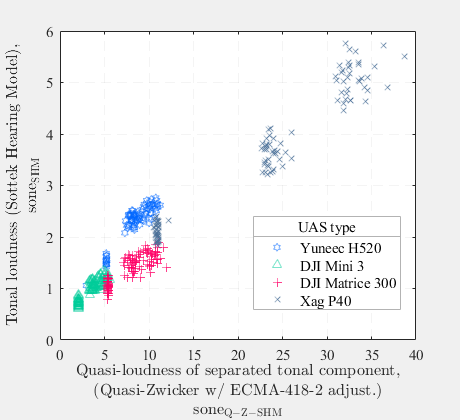

aurMask = contains(inFilePaths, ["_Aur", "Total_"]);
tonalMask = contains(inFilePaths, "Tonal");
bBandMask = contains(inFilePaths, "BroadBand");

TonalECMAAur = TonalECMA(aurMask);
LoudECMATonal = LoudECMA(tonalMask);
LoudQZ4182Tonal = LoudQZ4182(tonalMask);
LoudQZ4182BBand = LoudQZ4182(bBandMask);

labels = ["Yuneec H520", "DJI Mini 3", "DJI Matrice 300", "Xag P40"];

% plot
fig = figure;
fig.Visible = 'on';
fig.Position = [100, 100, 460, 420];
movegui(fig, 'center')
scatter([LoudQZ4182Tonal(contains([LoudQZ4182Tonal.File], "Yn_")).loudPowAvg],...
        [TonalECMAAur(contains([TonalECMAAur.File], "Yn_")).tonalLoudPowAvg], 'h',...
        'MarkerEdgeColor', mycolours(1, :), 'MarkerEdgeAlpha', 0.5)
hold on
scatter([LoudQZ4182Tonal(contains([LoudQZ4182Tonal.File], "3p_")).loudPowAvg],...
        [TonalECMAAur(contains([TonalECMAAur.File], "3p_")).tonalLoudPowAvg], '^',...
        'MarkerEdgeColor', mycolours(2, :), 'MarkerEdgeAlpha', 0.5)
scatter([LoudQZ4182Tonal(contains([LoudQZ4182Tonal.File], "M3_")).loudPowAvg],...
        [TonalECMAAur(contains([TonalECMAAur.File], "M3_")).tonalLoudPowAvg], '+',...
        'MarkerEdgeColor', mycolours(3, :), 'MarkerEdgeAlpha', 0.5)
scatter([LoudQZ4182Tonal(contains([LoudQZ4182Tonal.File], "X1_")).loudPowAvg],...
        [TonalECMAAur(contains([TonalECMAAur.File], "X1_")).tonalLoudPowAvg], 'x',...
        'MarkerEdgeColor', mycolours(4, :), 'MarkerEdgeAlpha', 0.5)
hold off
xlabel(["Quasi-loudness of separated tonal component,"; "(Quasi-Zwicker w/ ECMA-418-2 adjust.)"; "sone$_\mathrm{Q-Z-SHM}$"], 'Interpreter', 'latex')
ylabel(["Tonal loudness (Sottek Hearing Model),"; "sone$_\mathrm{SHM}$"], 'Interpreter', 'latex')
lgd = legend(labels, 'Location', 'best');
lgd.FontSize = 11;
lgd.EdgeColor = [0.7, 0.7, 0.7];
lgd.Title.String = "UAS type";
lgd.Title.FontWeight = 'normal';
grid('on')
set(gca, 'FontSize', 11, 'FontName', 'Times New Roman', 'GridAlpha', 0.05, 'GridLineStyle', '--')
ax = findall(fig, 'Type', 'axes');
set(ax, 'Box', 'on')
% save
filename = "LoudTQvTonLdSHM_AllSynth";
tb = axtoolbar(gca);
exportgraphics(fig, fullfile(outputPath, filename + ".pdf"), 'ContentType', 'vector')

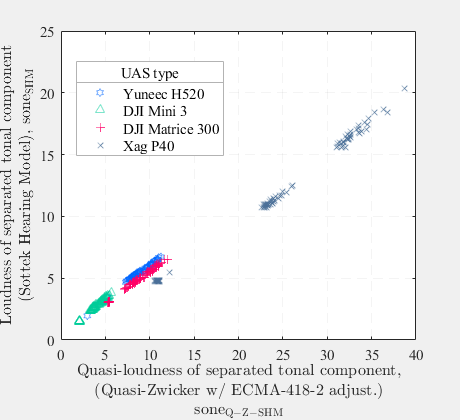


% plot
fig = figure;
fig.Visible = 'on';
fig.Position = [100, 100, 460, 420];
movegui(fig, 'center')
scatter([LoudQZ4182Tonal(contains([LoudQZ4182Tonal.File], "Yn_")).loudPowAvg],...
        [LoudECMATonal(contains([LoudECMATonal.File], "Yn_")).loudnessPowAvg], 'h',...
        'MarkerEdgeColor', mycolours(1, :), 'MarkerEdgeAlpha', 0.5)
hold on
scatter([LoudQZ4182Tonal(contains([LoudQZ4182Tonal.File], "3p_")).loudPowAvg],...
        [LoudECMATonal(contains([LoudECMATonal.File], "3p_")).loudnessPowAvg], '^',...
        'MarkerEdgeColor', mycolours(2, :), 'MarkerEdgeAlpha', 0.5)
scatter([LoudQZ4182Tonal(contains([LoudQZ4182Tonal.File], "M3_")).loudPowAvg],...
        [LoudECMATonal(contains([LoudECMATonal.File], "M3_")).loudnessPowAvg], '+',...
        'MarkerEdgeColor', mycolours(3, :), 'MarkerEdgeAlpha', 0.5)
scatter([LoudQZ4182Tonal(contains([LoudQZ4182Tonal.File], "X1_")).loudPowAvg],...
        [LoudECMATonal(contains([LoudECMATonal.File], "X1_")).loudnessPowAvg], 'x',...
        'MarkerEdgeColor', mycolours(4, :), 'MarkerEdgeAlpha', 0.5)
hold off
xlabel(["Quasi-loudness of separated tonal component,"; "(Quasi-Zwicker w/ ECMA-418-2 adjust.)"; "sone$_\mathrm{Q-Z-SHM}$"], 'Interpreter', 'latex')
ylabel(["Loudness of separated tonal component"; "(Sottek Hearing Model), sone$_\mathrm{SHM}$"], 'Interpreter', 'latex')
lgd = legend(labels, 'Location', 'best');
lgd.FontSize = 11;
lgd.EdgeColor = [0.7, 0.7, 0.7];
lgd.Title.String = "UAS type";
lgd.Title.FontWeight = 'normal';
grid('on')
set(gca, 'FontSize', 11, 'FontName', 'Times New Roman', 'GridAlpha', 0.05, 'GridLineStyle', '--')
ax = findall(fig, 'Type', 'axes');
set(ax, 'Box', 'on')
% save
filename = "LoudTQvLoudTSHM_AllSynth";
tb = axtoolbar(gca);
exportgraphics(fig, fullfile(outputPath, filename + ".pdf"), 'ContentType', 'vector')

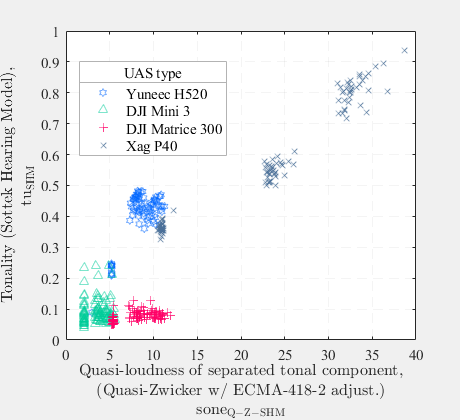


% plot
fig = figure;
fig.Visible = 'on';
fig.Position = [100, 100, 460, 420];
movegui(fig, 'center')
scatter([LoudQZ4182Tonal(contains([LoudQZ4182Tonal.File], "Yn_")).loudPowAvg],...
        [TonalECMAAur(contains([TonalECMAAur.File], "Yn_")).tonalityAvg], 'h',...
        'MarkerEdgeColor', mycolours(1, :), 'MarkerEdgeAlpha', 0.5)
hold on
scatter([LoudQZ4182Tonal(contains([LoudQZ4182Tonal.File], "3p_")).loudPowAvg],...
        [TonalECMAAur(contains([TonalECMAAur.File], "3p_")).tonalityAvg], '^',...
        'MarkerEdgeColor', mycolours(2, :), 'MarkerEdgeAlpha', 0.5)
scatter([LoudQZ4182Tonal(contains([LoudQZ4182Tonal.File], "M3_")).loudPowAvg],...
        [TonalECMAAur(contains([TonalECMAAur.File], "M3_")).tonalityAvg], '+',...
        'MarkerEdgeColor', mycolours(3, :), 'MarkerEdgeAlpha', 0.5)
scatter([LoudQZ4182Tonal(contains([LoudQZ4182Tonal.File], "X1_")).loudPowAvg],...
        [TonalECMAAur(contains([TonalECMAAur.File], "X1_")).tonalityAvg], 'x',...
        'MarkerEdgeColor', mycolours(4, :), 'MarkerEdgeAlpha', 0.5)
hold off
xlabel(["Quasi-loudness of separated tonal component,"; "(Quasi-Zwicker w/ ECMA-418-2 adjust.)"; "sone$_\mathrm{Q-Z-SHM}$"], 'Interpreter', 'latex')
ylabel(["Tonality (Sottek Hearing Model),"; "tu$_\mathrm{SHM}$"], 'Interpreter', 'latex')
lgd = legend(labels, 'Location', 'best');
lgd.FontSize = 11;
lgd.EdgeColor = [0.7, 0.7, 0.7];
lgd.Title.String = "UAS type";
lgd.Title.FontWeight = 'normal';
grid('on')
set(gca, 'FontSize', 11, 'FontName', 'Times New Roman', 'GridAlpha', 0.05, 'GridLineStyle', '--')
ax = findall(fig, 'Type', 'axes');
set(ax, 'Box', 'on')
% save
filename = "LoudTQvTonalSHM_AllSynth";
tb = axtoolbar(gca);
exportgraphics(fig, fullfile(outputPath, filename + ".pdf"), 'ContentType', 'vector')

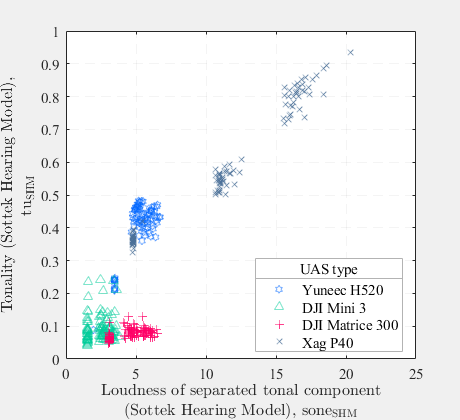


% plot
fig = figure;
fig.Visible = 'on';
fig.Position = [100, 100, 460, 420];
movegui(fig, 'center')
scatter([LoudECMATonal(contains([LoudECMATonal.File], "Yn_")).loudnessPowAvg],...
        [TonalECMAAur(contains([TonalECMAAur.File], "Yn_")).tonalityAvg], 'h',...
        'MarkerEdgeColor', mycolours(1, :), 'MarkerEdgeAlpha', 0.5)
hold on
scatter([LoudECMATonal(contains([LoudECMATonal.File], "3p_")).loudnessPowAvg],...
        [TonalECMAAur(contains([TonalECMAAur.File], "3p_")).tonalityAvg], '^',...
        'MarkerEdgeColor', mycolours(2, :), 'MarkerEdgeAlpha', 0.5)
scatter([LoudECMATonal(contains([LoudECMATonal.File], "M3_")).loudnessPowAvg],...
        [TonalECMAAur(contains([TonalECMAAur.File], "M3_")).tonalityAvg], '+',...
        'MarkerEdgeColor', mycolours(3, :), 'MarkerEdgeAlpha', 0.5)
scatter([LoudECMATonal(contains([LoudECMATonal.File], "X1_")).loudnessPowAvg],...
        [TonalECMAAur(contains([TonalECMAAur.File], "X1_")).tonalityAvg], 'x',...
        'MarkerEdgeColor', mycolours(4, :), 'MarkerEdgeAlpha', 0.5)
hold off
xlabel(["Loudness of separated tonal component"; "(Sottek Hearing Model), sone$_\mathrm{SHM}$"], 'Interpreter', 'latex')
ylabel(["Tonality (Sottek Hearing Model),"; "tu$_\mathrm{SHM}$"], 'Interpreter', 'latex')
lgd = legend(labels, 'Location', 'best');
lgd.FontSize = 11;
lgd.EdgeColor = [0.7, 0.7, 0.7];
lgd.Title.String = "UAS type";
lgd.Title.FontWeight = 'normal';
grid('on')
set(gca, 'FontSize', 11, 'FontName', 'Times New Roman', 'GridAlpha', 0.05, 'GridLineStyle', '--')
ax = findall(fig, 'Type', 'axes');
set(ax, 'Box', 'on')
% save
filename = "LoudTSHMvTonalSHM_AllSynth";
tb = axtoolbar(gca);
exportgraphics(fig, fullfile(outputPath, filename + ".pdf"), 'ContentType', 'vector')

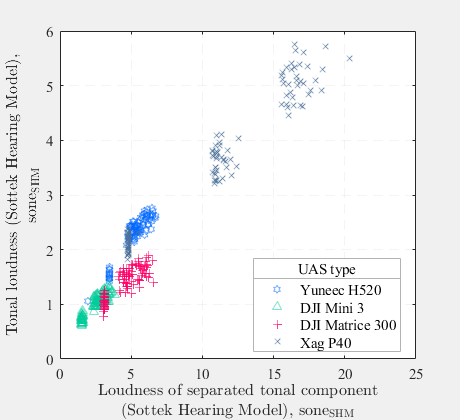


% plot
fig = figure;
fig.Visible = 'on';
fig.Position = [100, 100, 460, 420];
movegui(fig, 'center')
scatter([LoudECMATonal(contains([LoudECMATonal.File], "Yn_")).loudnessPowAvg],...
        [TonalECMAAur(contains([TonalECMAAur.File], "Yn_")).tonalLoudPowAvg], 'h',...
        'MarkerEdgeColor', mycolours(1, :), 'MarkerEdgeAlpha', 0.5)
hold on
scatter([LoudECMATonal(contains([LoudECMATonal.File], "3p_")).loudnessPowAvg],...
        [TonalECMAAur(contains([TonalECMAAur.File], "3p_")).tonalLoudPowAvg], '^',...
        'MarkerEdgeColor', mycolours(2, :), 'MarkerEdgeAlpha', 0.5)
scatter([LoudECMATonal(contains([LoudECMATonal.File], "M3_")).loudnessPowAvg],...
        [TonalECMAAur(contains([TonalECMAAur.File], "M3_")).tonalLoudPowAvg], '+',...
        'MarkerEdgeColor', mycolours(3, :), 'MarkerEdgeAlpha', 0.5)
scatter([LoudECMATonal(contains([LoudECMATonal.File], "X1_")).loudnessPowAvg],...
        [TonalECMAAur(contains([TonalECMAAur.File], "X1_")).tonalLoudPowAvg], 'x',...
        'MarkerEdgeColor', mycolours(4, :), 'MarkerEdgeAlpha', 0.5)
hold off
xlabel(["Loudness of separated tonal component"; "(Sottek Hearing Model), sone$_\mathrm{SHM}$"], 'Interpreter', 'latex')
ylabel(["Tonal loudness (Sottek Hearing Model),"; "sone$_\mathrm{SHM}$"], 'Interpreter', 'latex')
lgd = legend(labels, 'Location', 'best');
lgd.FontSize = 11;
lgd.EdgeColor = [0.7, 0.7, 0.7];
lgd.Title.String = "UAS type";
lgd.Title.FontWeight = 'normal';
grid('on')
set(gca, 'FontSize', 11, 'FontName', 'Times New Roman', 'GridAlpha', 0.05, 'GridLineStyle', '--')
ax = findall(fig, 'Type', 'axes');
set(ax, 'Box', 'on')
% save
filename = "LoudTSHMvTonLdSHM_AllSynth";
tb = axtoolbar(gca);
exportgraphics(fig, fullfile(outputPath, filename + ".pdf"), 'ContentType', 'vector')

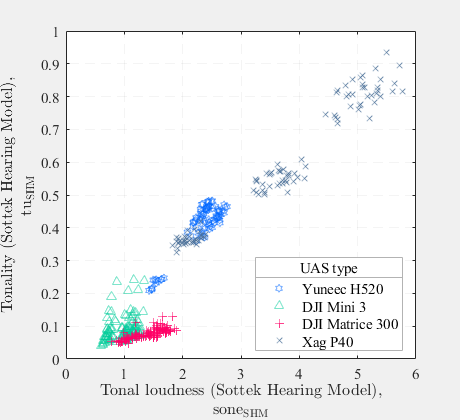


% plot
fig = figure;
fig.Visible = 'on';
fig.Position = [100, 100, 460, 420];
movegui(fig, 'center')
scatter([TonalECMAAur(contains([TonalECMAAur.File], "Yn_")).tonalLoudPowAvg],...
        [TonalECMAAur(contains([TonalECMAAur.File], "Yn_")).tonalityAvg], 'h',...
        'MarkerEdgeColor', mycolours(1, :), 'MarkerEdgeAlpha', 0.5)
hold on
scatter([TonalECMAAur(contains([TonalECMAAur.File], "3p_")).tonalLoudPowAvg],...
        [TonalECMAAur(contains([TonalECMAAur.File], "3p_")).tonalityAvg], '^',...
        'MarkerEdgeColor', mycolours(2, :), 'MarkerEdgeAlpha', 0.5)
scatter([TonalECMAAur(contains([TonalECMAAur.File], "M3_")).tonalLoudPowAvg],...
        [TonalECMAAur(contains([TonalECMAAur.File], "M3_")).tonalityAvg], '+',...
        'MarkerEdgeColor', mycolours(3, :), 'MarkerEdgeAlpha', 0.5)
scatter([TonalECMAAur(contains([TonalECMAAur.File], "X1_")).tonalLoudPowAvg],...
        [TonalECMAAur(contains([TonalECMAAur.File], "X1_")).tonalityAvg], 'x',...
        'MarkerEdgeColor', mycolours(4, :), 'MarkerEdgeAlpha', 0.5)
hold off
xlabel(["Tonal loudness (Sottek Hearing Model),"; "sone$_\mathrm{SHM}$"], 'Interpreter', 'latex')
ylabel(["Tonality (Sottek Hearing Model),"; "tu$_\mathrm{SHM}$"], 'Interpreter', 'latex')
lgd = legend(labels, 'Location', 'best');
lgd.FontSize = 11;
lgd.EdgeColor = [0.7, 0.7, 0.7];
lgd.Title.String = "UAS type";
lgd.Title.FontWeight = 'normal';
grid('on')
set(gca, 'FontSize', 11, 'FontName', 'Times New Roman', 'GridAlpha', 0.05, 'GridLineStyle', '--')
ax = findall(fig, 'Type', 'axes');
set(ax, 'Box', 'on')
% save
filename = "TonLdSHMvTonalSHM_AllSynth";
tb = axtoolbar(gca);
exportgraphics(fig, fullfile(outputPath, filename + ".pdf"), 'ContentType', 'vector')

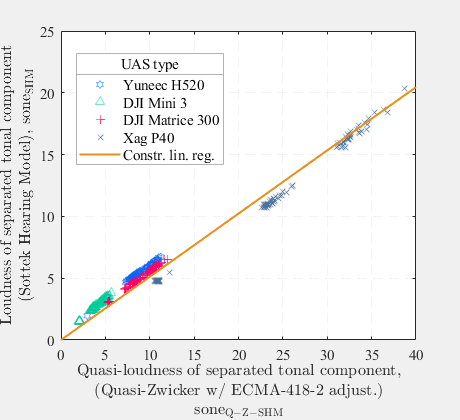

% determine linear regression between quasi-loudness and full loudness for
% tonal component

linCoeffs = polyfit([LoudQZ4182Tonal.loudPowAvg],...
                    [LoudECMATonal.loudnessPowAvg], 1);

mdl1 = fitlm([LoudQZ4182Tonal.loudPowAvg],...
             [LoudECMATonal.loudnessPowAvg], 'y ~ x1 - 1');

% plot mdl1
labels = ["Yuneec H520", "DJI Mini 3", "DJI Matrice 300", "Xag P40", "Constr. lin. reg."];
x = linspace(0, 40, 1000);
y = mdl1.Coefficients.Estimate.*x;
fig = figure;
fig.Visible = 'on';
fig.Position = [100, 100, 460, 420];
movegui(fig, 'center')
scatter([LoudQZ4182Tonal(contains([LoudQZ4182Tonal.File], "Yn_")).loudPowAvg],...
        [LoudECMATonal(contains([LoudECMATonal.File], "Yn_")).loudnessPowAvg], 'h',...
        'MarkerEdgeColor', mycolours(1, :), 'MarkerEdgeAlpha', 0.5)
hold on
scatter([LoudQZ4182Tonal(contains([LoudQZ4182Tonal.File], "3p_")).loudPowAvg],...
        [LoudECMATonal(contains([LoudECMATonal.File], "3p_")).loudnessPowAvg], '^',...
        'MarkerEdgeColor', mycolours(2, :), 'MarkerEdgeAlpha', 0.5)
scatter([LoudQZ4182Tonal(contains([LoudQZ4182Tonal.File], "M3_")).loudPowAvg],...
        [LoudECMATonal(contains([LoudECMATonal.File], "M3_")).loudnessPowAvg], '+',...
        'MarkerEdgeColor', mycolours(3, :), 'MarkerEdgeAlpha', 0.5)
scatter([LoudQZ4182Tonal(contains([LoudQZ4182Tonal.File], "X1_")).loudPowAvg],...
        [LoudECMATonal(contains([LoudECMATonal.File], "X1_")).loudnessPowAvg], 'x',...
        'MarkerEdgeColor', mycolours(4, :), 'MarkerEdgeAlpha', 0.5)
plot(x, y, '-', 'color', mycolours(5, :), 'LineWidth', 1.5)
hold off
xlabel(["Quasi-loudness of separated tonal component,"; "(Quasi-Zwicker w/ ECMA-418-2 adjust.)"; "sone$_\mathrm{Q-Z-SHM}$"], 'Interpreter', 'latex')
ylabel(["Loudness of separated tonal component"; "(Sottek Hearing Model), sone$_\mathrm{SHM}$"], 'Interpreter', 'latex')
lgd = legend(labels, 'Location', 'best');
lgd.FontSize = 11;
lgd.EdgeColor = [0.7, 0.7, 0.7];
lgd.Title.String = "UAS type";
lgd.Title.FontWeight = 'normal';
grid('on')
set(gca, 'FontSize', 11, 'FontName', 'Times New Roman', 'GridAlpha', 0.05, 'GridLineStyle', '--')
ax = findall(fig, 'Type', 'axes');
set(ax, 'Box', 'on')
% save
filename = "LoudTQvLoudTSHMReg_AllSynth";
tb = axtoolbar(gca);
exportgraphics(fig, fullfile(outputPath, filename + ".pdf"), 'ContentType', 'vector')

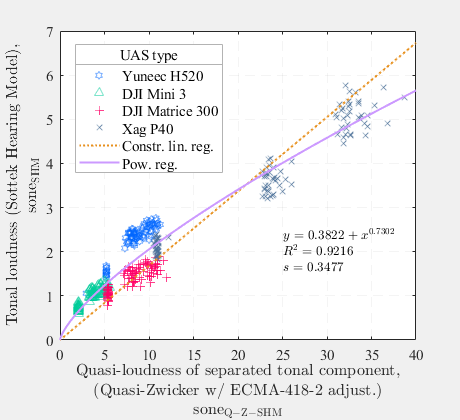



% models for tonal loudness
% constrained linear
mdl2 = fitlm([LoudQZ4182Tonal.loudPowAvg],...
             [TonalECMAAur.tonalLoudPowAvg], 'y ~ x1 - 1');


% power function
[mdl3, mdl3gof, mdl3out] = fit([LoudQZ4182Tonal.loudPowAvg].',...
                               [TonalECMAAur.tonalLoudPowAvg].', 'power1');
mdl3coeffs = coeffvalues(mdl3);

% plot mdl2 and mdl3
labels = ["Yuneec H520", "DJI Mini 3", "DJI Matrice 300", "Xag P40", "Constr. lin. reg.", "Pow. reg."];
x = linspace(0, 40, 1000);
y0 = mdl2.Coefficients.Estimate.*x;
y1 = mdl3.a.*x.^mdl3.b;
fig = figure;
fig.Visible = 'on';
fig.Position = [100, 100, 460, 420];
movegui(fig, 'center')
scatter([LoudQZ4182Tonal(contains([LoudQZ4182Tonal.File], "Yn_")).loudPowAvg],...
        [TonalECMAAur(contains([TonalECMAAur.File], "Yn_")).tonalLoudPowAvg], 'h',...
        'MarkerEdgeColor', mycolours(1, :), 'MarkerEdgeAlpha', 0.5)
hold on
scatter([LoudQZ4182Tonal(contains([LoudQZ4182Tonal.File], "3p_")).loudPowAvg],...
        [TonalECMAAur(contains([TonalECMAAur.File], "3p_")).tonalLoudPowAvg], '^',...
        'MarkerEdgeColor', mycolours(2, :), 'MarkerEdgeAlpha', 0.5)
scatter([LoudQZ4182Tonal(contains([LoudQZ4182Tonal.File], "M3_")).loudPowAvg],...
        [TonalECMAAur(contains([TonalECMAAur.File], "M3_")).tonalLoudPowAvg], '+',...
        'MarkerEdgeColor', mycolours(3, :), 'MarkerEdgeAlpha', 0.5)
scatter([LoudQZ4182Tonal(contains([LoudQZ4182Tonal.File], "X1_")).loudPowAvg],...
        [TonalECMAAur(contains([TonalECMAAur.File], "X1_")).tonalLoudPowAvg], 'x',...
        'MarkerEdgeColor', mycolours(4, :), 'MarkerEdgeAlpha', 0.5)
plot(x, y0, ':', 'color', mycolours(5, :), 'LineWidth', 1.5)
plot(x, y1, '-', 'color', mycolours(6, :), 'LineWidth', 1.5)
hold off
xlabel(["Quasi-loudness of separated tonal component,"; "(Quasi-Zwicker w/ ECMA-418-2 adjust.)"; "sone$_\mathrm{Q-Z-SHM}$"], 'Interpreter', 'latex')
ylabel(["Tonal loudness (Sottek Hearing Model),"; "sone$_\mathrm{SHM}$"], 'Interpreter', 'latex')
text(25, 2, [sprintf("$y = %0.4f + x^{%0.4f}$", round(mdl3coeffs(1), 4), round(mdl3coeffs(2), 4));
             sprintf("$R^2 = %0.4f$", mdl3gof.rsquare);
             sprintf("$s = %0.4f$ (sone)", mdl3gof.rmse)], 'Interpreter', 'latex')
lgd = legend(labels, 'Location', 'best');
lgd.FontSize = 11;
lgd.EdgeColor = [0.7, 0.7, 0.7];
lgd.Title.String = "UAS type";
lgd.Title.FontWeight = 'normal';
grid('on')
set(gca, 'FontSize', 11, 'FontName', 'Times New Roman', 'GridAlpha', 0.05, 'GridLineStyle', '--')
ax = findall(fig, 'Type', 'axes');
set(ax, 'Box', 'on')
% save
filename = "LoudTQvTonLdSHMReg_AllSynth";
tb = axtoolbar(gca);
exportgraphics(fig, fullfile(outputPath, filename + ".pdf"), 'ContentType', 'vector')

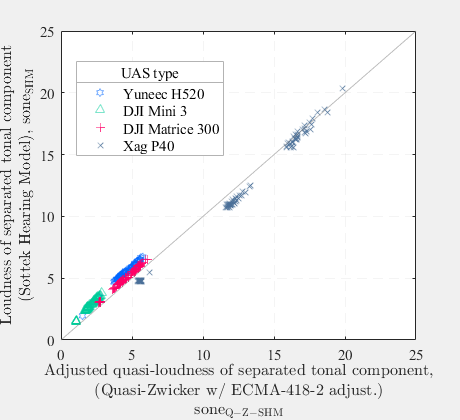

% recalculate quasi-loudness using regression coefficients
labels = ["Yuneec H520", "DJI Mini 3", "DJI Matrice 300", "Xag P40"];

% loudness of tonal component
% plot
fig = figure;
fig.Visible = 'on';
fig.Position = [100, 100, 460, 420];
movegui(fig, 'center')
scatter(mdl1.Coefficients.Estimate*[LoudQZ4182Tonal(contains([LoudQZ4182Tonal.File], "Yn_")).loudPowAvg],...
        [LoudECMATonal(contains([LoudECMATonal.File], "Yn_")).loudnessPowAvg], 'h',...
        'MarkerEdgeColor', mycolours(1, :), 'MarkerEdgeAlpha', 0.5)
hold on
scatter(mdl1.Coefficients.Estimate*[LoudQZ4182Tonal(contains([LoudQZ4182Tonal.File], "3p_")).loudPowAvg],...
        [LoudECMATonal(contains([LoudECMATonal.File], "3p_")).loudnessPowAvg], '^',...
        'MarkerEdgeColor', mycolours(2, :), 'MarkerEdgeAlpha', 0.5)
scatter(mdl1.Coefficients.Estimate*[LoudQZ4182Tonal(contains([LoudQZ4182Tonal.File], "M3_")).loudPowAvg],...
        [LoudECMATonal(contains([LoudECMATonal.File], "M3_")).loudnessPowAvg], '+',...
        'MarkerEdgeColor', mycolours(3, :), 'MarkerEdgeAlpha', 0.5)
scatter(mdl1.Coefficients.Estimate*[LoudQZ4182Tonal(contains([LoudQZ4182Tonal.File], "X1_")).loudPowAvg],...
        [LoudECMATonal(contains([LoudECMATonal.File], "X1_")).loudnessPowAvg], 'x',...
        'MarkerEdgeColor', mycolours(4, :), 'MarkerEdgeAlpha', 0.5)
plot(linspace(0, 25, 25), linspace(0, 25, 25), 'color', [0.5, 0.5, 0.5, 0.5])
hold off
xlabel(["Adjusted quasi-loudness of separated tonal component,"; "(Quasi-Zwicker w/ ECMA-418-2 adjust.)"; "sone$_\mathrm{Q-Z-SHM}$"], 'Interpreter', 'latex')
ylabel(["Loudness of separated tonal component"; "(Sottek Hearing Model), sone$_\mathrm{SHM}$"], 'Interpreter', 'latex')
lgd = legend(labels, 'Location', 'best');
lgd.FontSize = 11;
lgd.EdgeColor = [0.7, 0.7, 0.7];
lgd.Title.String = "UAS type";
lgd.Title.FontWeight = 'normal';
grid('on')
set(gca, 'FontSize', 11, 'FontName', 'Times New Roman', 'GridAlpha', 0.05, 'GridLineStyle', '--')
ax = findall(fig, 'Type', 'axes');
set(ax, 'Box', 'on')
axis([0, 25, 0, 25])
% save
filename = "LoudTQAdjvLoudTSHM_AllSynth";
tb = axtoolbar(gca);
exportgraphics(fig, fullfile(outputPath, filename + ".pdf"), 'ContentType', 'vector')

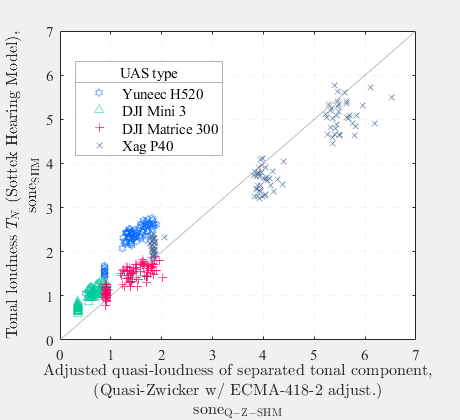



% tonal loudness
% plot
fig = figure;
fig.Visible = 'on';
fig.Position = [100, 100, 460, 420];
movegui(fig, 'center')
scatter(mdl2.Coefficients.Estimate*[LoudQZ4182Tonal(contains([LoudQZ4182Tonal.File], "Yn_")).loudPowAvg],...
        [TonalECMAAur(contains([TonalECMAAur.File], "Yn_")).tonalLoudPowAvg], 'h',...
        'MarkerEdgeColor', mycolours(1, :), 'MarkerEdgeAlpha', 0.5)
hold on
scatter(mdl2.Coefficients.Estimate*[LoudQZ4182Tonal(contains([LoudQZ4182Tonal.File], "3p_")).loudPowAvg],...
        [TonalECMAAur(contains([TonalECMAAur.File], "3p_")).tonalLoudPowAvg], '^',...
        'MarkerEdgeColor', mycolours(2, :), 'MarkerEdgeAlpha', 0.5)
scatter(mdl2.Coefficients.Estimate*[LoudQZ4182Tonal(contains([LoudQZ4182Tonal.File], "M3_")).loudPowAvg],...
        [TonalECMAAur(contains([TonalECMAAur.File], "M3_")).tonalLoudPowAvg], '+',...
        'MarkerEdgeColor', mycolours(3, :), 'MarkerEdgeAlpha', 0.5)
scatter(mdl2.Coefficients.Estimate*[LoudQZ4182Tonal(contains([LoudQZ4182Tonal.File], "X1_")).loudPowAvg],...
        [TonalECMAAur(contains([TonalECMAAur.File], "X1_")).tonalLoudPowAvg], 'x',...
        'MarkerEdgeColor', mycolours(4, :), 'MarkerEdgeAlpha', 0.5)
plot(linspace(0, 7, 7), linspace(0, 7, 7), 'color', [0.5, 0.5, 0.5, 0.5])
hold off
xlabel(["Adjusted quasi-loudness of separated tonal component,"; "(Quasi-Zwicker w/ ECMA-418-2 adjust.)"; "sone$_\mathrm{Q-Z-SHM}$"], 'Interpreter', 'latex')
ylabel(["Tonal loudness $T_N$ (Sottek Hearing Model),"; "sone$_\mathrm{SHM}$"], 'Interpreter', 'latex')
lgd = legend(labels, 'Location', 'best');
lgd.FontSize = 11;
lgd.EdgeColor = [0.7, 0.7, 0.7];
lgd.Title.String = "UAS type";
lgd.Title.FontWeight = 'normal';
grid('on')
set(gca, 'FontSize', 11, 'FontName', 'Times New Roman', 'GridAlpha', 0.05, 'GridLineStyle', '--')
ax = findall(fig, 'Type', 'axes');
set(ax, 'Box', 'on')
% save
filename = "LoudTQAdjvTonLdSHM_AllSynth";
tb = axtoolbar(gca);
exportgraphics(fig, fullfile(outputPath, filename + ".pdf"), 'ContentType', 'vector')

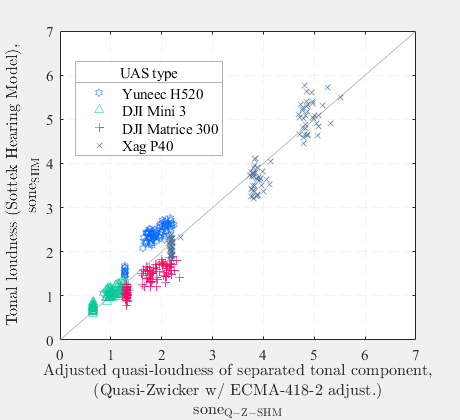



% plot
fig = figure;
fig.Visible = 'on';
fig.Position = [100, 100, 460, 420];
movegui(fig, 'center')
scatter(mdl3.a.*[LoudQZ4182Tonal(contains([LoudQZ4182Tonal.File], "Yn_")).loudPowAvg].^mdl3.b,...
        [TonalECMAAur(contains([TonalECMAAur.File], "Yn_")).tonalLoudPowAvg], 'h',...
        'MarkerEdgeColor', mycolours(1, :), 'MarkerEdgeAlpha', 0.5)
hold on
scatter(mdl3.a.*[LoudQZ4182Tonal(contains([LoudQZ4182Tonal.File], "3p_")).loudPowAvg].^mdl3.b,...
        [TonalECMAAur(contains([TonalECMAAur.File], "3p_")).tonalLoudPowAvg], '^',...
        'MarkerEdgeColor', mycolours(2, :), 'MarkerEdgeAlpha', 0.5)
scatter(mdl3.a.*[LoudQZ4182Tonal(contains([LoudQZ4182Tonal.File], "M3_")).loudPowAvg].^mdl3.b,...
        [TonalECMAAur(contains([TonalECMAAur.File], "M3_")).tonalLoudPowAvg], '+',...
        'MarkerEdgeColor', mycolours(3, :), 'MarkerEdgeAlpha', 0.5)
scatter(mdl3.a.*[LoudQZ4182Tonal(contains([LoudQZ4182Tonal.File], "X1_")).loudPowAvg].^mdl3.b,...
        [TonalECMAAur(contains([TonalECMAAur.File], "X1_")).tonalLoudPowAvg], 'x',...
        'MarkerEdgeColor', mycolours(4, :), 'MarkerEdgeAlpha', 0.5)
plot(linspace(0, 7, 7), linspace(0, 7, 7), 'color', [0.5, 0.5, 0.5, 0.5])
hold off
xlabel(["Adjusted quasi-loudness of separated tonal component,"; "(Quasi-Zwicker w/ ECMA-418-2 adjust.)"; "sone$_\mathrm{Q-Z-SHM}$"], 'Interpreter', 'latex')
ylabel(["Tonal loudness (Sottek Hearing Model),"; "sone$_\mathrm{SHM}$"], 'Interpreter', 'latex')
lgd = legend(labels, 'Location', 'best');
lgd.FontSize = 11;
lgd.EdgeColor = [0.7, 0.7, 0.7];
lgd.Title.String = "UAS type";
lgd.Title.FontWeight = 'normal';
grid('on')
set(gca, 'FontSize', 11, 'FontName', 'Times New Roman', 'GridAlpha', 0.05, 'GridLineStyle', '--')
ax = findall(fig, 'Type', 'axes');
set(ax, 'Box', 'on')
% save
filename = "LoudTQAdjPowvTonLdSHM_AllSynth";
tb = axtoolbar(gca);
exportgraphics(fig, fullfile(outputPath, filename + ".pdf"), 'ContentType', 'vector')

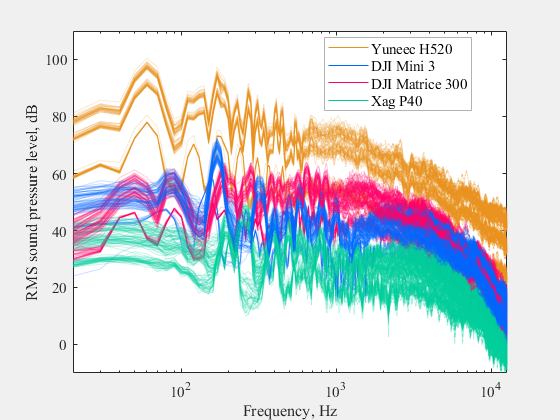

% Plot spectra for Yuneec and Matrice

fig = figure;
fig.Visible = 'on';
movegui(fig, 'center')
alphaVal = 0.2;

aurFiles = inFilePaths(aurMask);

% dummy objects for legend
semilogx([0, 0], [0, 0], 'Color', [mycolours(4, :)], 'DisplayName', "Xag P40")
hold on
semilogx([0, 0], [0, 0], 'Color', [mycolours(1, :)], 'DisplayName', "Yuneec H520")
semilogx([0, 0], [0, 0], 'Color', [mycolours(3, :)], 'DisplayName', "DJI Matrice 300")
semilogx([0, 0], [0, 0], 'Color', [mycolours(2, :)], 'DisplayName', "DJI Mini 3")

for ii = 1:length(aurFiles)
    if contains(aurFiles(ii), "X1")
        [p, fs] = audioread(aurFiles(ii));
        nfft = fs/10;

        [pxxf, pxx, Ben] = rfft_aspec(p, fs, nfft, 1, 0.5, 'hann', 'rms');

        semilogx(pxxf, 20*log10(pxx/2e-5), 'Color', [mycolours(4, :), alphaVal], 'HandleVisibility', 'off')

        hold on
    elseif contains(aurFiles(ii), "M3")
        [p, fs] = audioread(aurFiles(ii));
        nfft = fs/10;

        [pxxf, pxx, Ben] = rfft_aspec(p, fs, nfft, 1, 0.5, 'hann', 'rms');

        semilogx(pxxf, 20*log10(pxx/2e-5), 'Color', [mycolours(3, :), alphaVal], 'HandleVisibility', 'off')
        
        hold on
    elseif contains(aurFiles(ii), "Yn")
        [p, fs] = audioread(aurFiles(ii));
        nfft = fs/10;

        [pxxf, pxx, Ben] = rfft_aspec(p, fs, nfft, 1, 0.5, 'hann', 'rms');

        semilogx(pxxf, 20*log10(pxx/2e-5), 'Color', [mycolours(1, :), alphaVal], 'HandleVisibility', 'off')

        hold on
    elseif contains(aurFiles(ii), "3p")
        [p, fs] = audioread(aurFiles(ii));
        nfft = fs/10;

        [pxxf, pxx, Ben] = rfft_aspec(p, fs, nfft, 1, 0.5, 'hann', 'rms');

        semilogx(pxxf, 20*log10(pxx/2e-5), 'Color', [mycolours(2, :), alphaVal], 'HandleVisibility', 'off')

        hold on
    end
end
hold off
axis([20, 12600, -10, 110])
xlabel("Frequency, Hz")
ylabel("RMS sound pressure level, dB")
lgd = legend(labels, 'Location', 'best');
lgd.FontSize = 11;
lgd.EdgeColor = [0.7, 0.7, 0.7];
set(gca, 'FontSize', 11, 'FontName', 'Times New Roman')
% save
filename = "TotalRMSSPLFFT_AllSynth";
tb = axtoolbar(gca);
exportgraphics(fig, fullfile(outputPath, filename + ".pdf"), 'ContentType', 'vector')

% Plot spectra for Yuneec and Matrice tonal components

fig = figure;
fig.Visible = 'on';
movegui(fig, 'center')
alphaVal = 0.2;

tonalFiles = inFilePaths(tonalMask);

% dummy objects for legend
semilogx([0, 0], [0, 0], 'Color', [mycolours(4, :)], 'DisplayName', "Xag P40")
hold on
semilogx([0, 0], [0, 0], 'Color', [mycolours(1, :)], 'DisplayName', "Yuneec H520")
semilogx([0, 0], [0, 0], 'Color', [mycolours(3, :)], 'DisplayName', "DJI Matrice 300")
semilogx([0, 0], [0, 0], 'Color', [mycolours(2, :)], 'DisplayName', "DJI Mini 3")

for ii = 1:length(tonalFiles)
    if contains(tonalFiles(ii), "X1")
        [p, fs] = audioread(tonalFiles(ii));
        nfft = fs/10;

        [pxxf, pxx, Ben] = rfft_aspec(p, fs, nfft, 1, 0.5, 'hann', 'rms');

        semilogx(pxxf, 20*log10(pxx/2e-5), 'Color', [mycolours(4, :), alphaVal], 'HandleVisibility', 'off')

        hold on
    elseif contains(tonalFiles(ii), "M3")
        [p, fs] = audioread(tonalFiles(ii));
        nfft = fs/10;

        [pxxf, pxx, Ben] = rfft_aspec(p, fs, nfft, 1, 0.5, 'hann', 'rms');

        semilogx(pxxf, 20*log10(pxx/2e-5), 'Color', [mycolours(3, :), alphaVal], 'HandleVisibility', 'off')

        hold on
    elseif contains(tonalFiles(ii), "Yn")
        [p, fs] = audioread(tonalFiles(ii));
        nfft = fs/10;

        [pxxf, pxx, Ben] = rfft_aspec(p, fs, nfft, 1, 0.5, 'hann', 'rms');

        semilogx(pxxf, 20*log10(pxx/2e-5), 'Color', [mycolours(1, :), alphaVal], 'HandleVisibility', 'off')

        hold on
    elseif contains(tonalFiles(ii), "3p")
        [p, fs] = audioread(tonalFiles(ii));
        nfft = fs/10;

        [pxxf, pxx, Ben] = rfft_aspec(p, fs, nfft, 1, 0.5, 'hann', 'rms');

        semilogx(pxxf, 20*log10(pxx/2e-5), 'Color', [mycolours(2, :), alphaVal], 'HandleVisibility', 'off')

        hold on
    end
end
hold off
xlabel("Frequency, Hz")
ylabel("RMS sound pressure level, dB")
axis([20, 12600, -10, 110])
lgd = legend(labels, 'Location', 'best');
lgd.FontSize = 11;
lgd.EdgeColor = [0.7, 0.7, 0.7];
set(gca, 'FontSize', 11, 'FontName', 'Times New Roman')
% save
filename = "TonalRMSSPLFFT_AllSynth";
tb = axtoolbar(gca);
exportgraphics(fig, fullfile(outputPath, filename + ".pdf"), 'ContentType', 'vector')

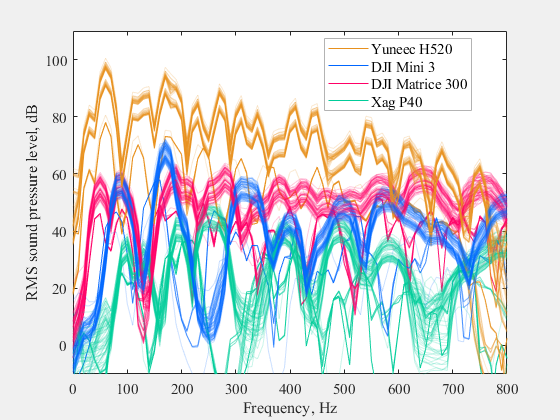


% save zoomed low-frequency with linear scale
set(gca, 'XScale', 'lin', 'XLim', [0, 800])
filename = "TonalRMSSPLFFTLnZm_AllSynth";
tb = axtoolbar(gca);
exportgraphics(fig, fullfile(outputPath, filename + ".pdf"), 'ContentType', 'vector')

## Helper functions

function [loudTDep, loudness] = loudOverall(specLoud)
    loudTDep = sum(specLoud, 2)*0.5;
    loudness = (sum(loudTDep((57 + 1):end, :).^(1/log10(2)), 1)./size(loudTDep((57 + 1):end, :), 1)).^log10(2);
end
